%% ============================================================
%  Bootstrap evaluation for 5 DAGNetwork models
%  Metrics:
%  ROC-AUC, accuracy, precision, recall, F1-score, 95% CI
%
%  适用于：
%  - 二分类
%  - 多分类
%  - 5折交叉验证得到的5个 DAGNetwork
%  - 测试集为 datastore
%% ============================================================

clc;
clear;

%加载临床测试集数据
load("Data_ClinicTest.mat");

%% 1. 加载保存的模型
nets = cell(1,5);%初始化 cell用于保存五折交叉验证所得到的每个DeepModel
Metrics_Deep_Array = repmat(table, 1,5); %预先分配table数组用于存储评估指标

%%依次加载训练好的模型
nets{1} = load("3DRESNetCV1-2025-09-18-01-51-03.mat");
nets{2} = load("3DRESNetCV2-2025-12-14-17-35-53.mat");
nets{3} = load("3DRESNetCV3-2025-12-18-21-07-23.mat");
nets{4} = load("3DRESNetCV4-2025-12-23-18-00-19.mat");
nets{5} = load("3DRESNetCV5-2025-12-28-02-44-33.mat");


modelNames = [
    "Fold1";
    "Fold2";
    "Fold3";
    "Fold4";
    "Fold5";
    "Ensemble"
];


%% 2. 测试集 datastore
% 这里替换为你的测试集 datastore 名称 临床测试集
testDS = Data_clinic_Test;

%% 3. 参数设置
B = 2000;                  % bootstrap次数
miniBatchSize = 16;         % 3D 224^3 通常建议从1开始，避免显存不足
rng(2026, 'twister');      % 固定随机种子，保证结果可重复

% 是否使用分层bootstrap
% 多分类或类别不均衡时强烈建议 true
useStratifiedBootstrap = true;

%% 4. 获取测试集真实标签
% 如果 testDS 有 Labels 属性，会自动读取
% 如果你的 datastore 没有 Labels 属性，请手动赋值：
% YTrue = categorical(yourTestLabels);

YTrue = getLabelsFromDatastore(testDS);

fprintf('\n测试集样本数: %d\n', numel(YTrue));


测试集样本数: 540


disp('测试集类别分布:');

测试集类别分布:


tabulate(YTrue);

        Value    Count   Percent
  BodyChanges       60     11.11%
    ErrorFree       60     11.11%
       Gantry       80     14.81%
         MLCR       60     11.11%
         MLCS       80     14.81%
           MU       80     14.81%
        SETUP      120     22.22%


%% 5. 对完整测试集进行一次预测
% scoreAll: N × K × 5
% N = 测试样本数
% K = 类别数
% 5 = 五个模型

[scoreAll, classes, YTrue] = predictScoresForFiveModels( ...
    nets, testDS, YTrue, miniBatchSize);


正在预测模型 1/5...
模型 1 预测完成。score size = [540    7]

正在预测模型 2/5...
模型 2 预测完成。score size = [540    7]

正在预测模型 3/5...
模型 3 预测完成。score size = [540    7]

正在预测模型 4/5...
模型 4 预测完成。score size = [540    7]

正在预测模型 5/5...
模型 5 预测完成。score size = [540    7]



numModels = size(scoreAll, 3);
numClasses = numel(classes);

fprintf('\n预测完成。\n');


预测完成。


fprintf('测试样本数 N = %d\n', size(scoreAll, 1));

测试样本数 N = 540


fprintf('类别数 K = %d\n', numClasses);

类别数 K = 7


fprintf('模型数 = %d\n', numModels);

模型数 = 5


%% 6. 构建5个单模型 + 1个集成模型的 score

scoreList = cell(numModels + 1, 1);

for m = 1:numModels
    scoreList{m} = scoreAll(:, :, m);
end

% Ensemble：对5个模型的预测概率取平均
scoreList{numModels + 1} = mean(scoreAll, 3);

%% 7. 逐模型进行 bootstrap 评估

allMetricTable = table();

for m = 1:numModels + 1

    fprintf('\n====================================================\n');
    fprintf('正在进行 bootstrap 评估: %s\n', modelNames(m));
    fprintf('====================================================\n');

    YScore = scoreList{m};

    [metricTable, bootMetrics, pointMetrics] = bootstrapMetricsWithCI( ...
        YTrue, YScore, classes, B, useStratifiedBootstrap);

    metricTable.Model = repmat(modelNames(m), height(metricTable), 1);
    metricTable = movevars(metricTable, 'Model', 'Before', 'Metric');

    allMetricTable = [allMetricTable; metricTable]; %#ok<AGROW>

    disp(metricTable);

end

正在进行 bootstrap 评估: Fold1


Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


     Model            Metric           Estimate    CI_2_5     CI_97_5
    _______    ____________________    ________    _______    _______

    "Fold1"    "Macro_AUC"             0.97199     0.96433    0.97879
    "Fold1"    "Accuracy"              0.81296     0.78148    0.84259
    "Fold1"    "Macro_Precision"       0.84461     0.81771    0.87143
    "Fold1"    "Macro_Recall"          0.82202     0.79226     0.8506
    "Fold1"    "Macro_F1"              0.82806     0.79937    0.85565
    "Fold1"    "Weighted_Precision"    0.82463     0.79636    0.85267
    "Fold1"    "Weighted_Recall"       0.81296     0.78148    0.84259
    "Fold1"    "Weighted_F1"           0.81413     0.78296    0.84369



正在进行 bootstrap 评估: Fold2


Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


     Model            Metric           Estimate    CI_2_5     CI_97_5
    _______    ____________________    ________    _______    _______

    "Fold2"    "Macro_AUC"             0.98637     0.98132    0.99055
    "Fold2"    "Accuracy"              0.85556     0.82778    0.88148
    "Fold2"    "Macro_Precision"       0.89453     0.87252    0.91539
    "Fold2"    "Macro_Recall"          0.84821     0.82083     0.8744
    "Fold2"    "Macro_F1"              0.85487     0.82524    0.88168
    "Fold2"    "Weighted_Precision"    0.88567     0.86357    0.90741
    "Fold2"    "Weighted_Recall"       0.85556     0.82778    0.88148
    "Fold2"    "Weighted_F1"           0.85547     0.82712    0.88119



正在进行 bootstrap 评估: Fold3


Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


     Model            Metric           Estimate    CI_2_5     CI_97_5
    _______    ____________________    ________    _______    _______

    "Fold3"    "Macro_AUC"             0.98221     0.97674    0.98725
    "Fold3"    "Accuracy"              0.84074     0.81296    0.86852
    "Fold3"    "Macro_Precision"       0.86974     0.84759    0.89329
    "Fold3"    "Macro_Recall"           0.8375     0.81012    0.86607
    "Fold3"    "Macro_F1"              0.83991     0.80846     0.8692
    "Fold3"    "Weighted_Precision"    0.85392      0.8304    0.87997
    "Fold3"    "Weighted_Recall"       0.84074     0.81296    0.86852
    "Fold3"    "Weighted_F1"           0.83596     0.80532    0.86546



正在进行 bootstrap 评估: Fold4


Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


     Model            Metric           Estimate    CI_2_5     CI_97_5
    _______    ____________________    ________    _______    _______

    "Fold4"    "Macro_AUC"             0.96767     0.95869    0.97621
    "Fold4"    "Accuracy"              0.83704     0.80926    0.86296
    "Fold4"    "Macro_Precision"       0.89052     0.87022    0.91028
    "Fold4"    "Macro_Recall"          0.82857      0.8003    0.85536
    "Fold4"    "Macro_F1"               0.8415     0.81045    0.86822
    "Fold4"    "Weighted_Precision"     0.8638     0.84216    0.88571
    "Fold4"    "Weighted_Recall"       0.83704     0.80926    0.86296
    "Fold4"    "Weighted_F1"           0.83293     0.80258    0.86023



正在进行 bootstrap 评估: Fold5


Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


     Model            Metric           Estimate    CI_2_5     CI_97_5
    _______    ____________________    ________    _______    _______

    "Fold5"    "Macro_AUC"             0.98803     0.98384    0.99189
    "Fold5"    "Accuracy"              0.85926     0.83148    0.88704
    "Fold5"    "Macro_Precision"       0.86423     0.83803    0.89176
    "Fold5"    "Macro_Recall"          0.86012     0.83244     0.8875
    "Fold5"    "Macro_F1"              0.85963     0.83179    0.88715
    "Fold5"    "Weighted_Precision"    0.86225     0.83547    0.89016
    "Fold5"    "Weighted_Recall"       0.85926     0.83148    0.88704
    "Fold5"    "Weighted_F1"           0.85815     0.83005     0.8859



正在进行 bootstrap 评估: Ensemble


Bootstrap 200 / 2000 completed.
Bootstrap 400 / 2000 completed.
Bootstrap 600 / 2000 completed.
Bootstrap 800 / 2000 completed.
Bootstrap 1000 / 2000 completed.
Bootstrap 1200 / 2000 completed.
Bootstrap 1400 / 2000 completed.
Bootstrap 1600 / 2000 completed.
Bootstrap 1800 / 2000 completed.
Bootstrap 2000 / 2000 completed.


      Model              Metric           Estimate    CI_2_5     CI_97_5
    __________    ____________________    ________    _______    _______

    "Ensemble"    "Macro_AUC"             0.98492     0.97981    0.98927
    "Ensemble"    "Accuracy"              0.86481     0.83889    0.88889
    "Ensemble"    "Macro_Precision"        0.9021     0.88372    0.92064
    "Ensemble"    "Macro_Recall"          0.85476     0.82619    0.88155
    "Ensemble"    "Macro_F1"              0.86578     0.83582    0.89179
    "Ensemble"    "Weighted_Precision"     0.8796      0.8585    0.90148
    "Ensemble"    "Weighted_Recall"       0.86481     0.83889    0.88889
    "Ensemble"    "Weighted_F1"           0.86058     0.83115    0.88673




%% 8. 保存总体指标结果

writetable(allMetricTable, 'Bootstrap_Metrics_Results.xlsx');

fprintf('\n总体指标已保存至: Bootstrap_Metrics_Results.xlsx\n');


总体指标已保存至: Bootstrap_Metrics_Results.xlsx



%% 9. 对 Ensemble 模型绘制带95%% CI的 ROC 曲线

ensembleScore = scoreList{end};

rocOut = bootstrapMacroROC( ...
    YTrue, ensembleScore, classes, B, useStratifiedBootstrap, 1001);

ROC Bootstrap 200 / 2000 completed.
ROC Bootstrap 400 / 2000 completed.
ROC Bootstrap 600 / 2000 completed.
ROC Bootstrap 800 / 2000 completed.
ROC Bootstrap 1000 / 2000 completed.
ROC Bootstrap 1200 / 2000 completed.
ROC Bootstrap 1400 / 2000 completed.
ROC Bootstrap 1600 / 2000 completed.
ROC Bootstrap 1800 / 2000 completed.
ROC Bootstrap 2000 / 2000 completed.


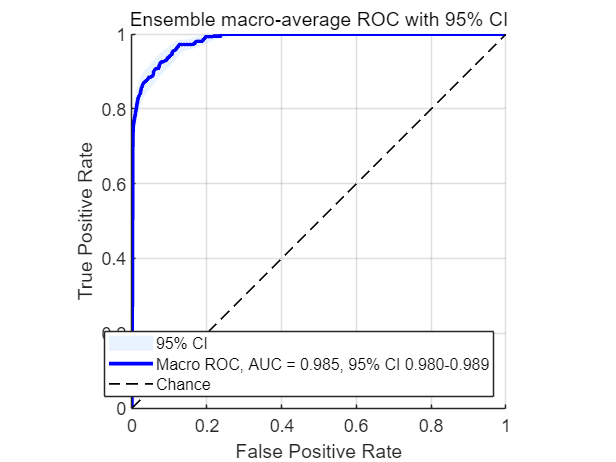


plotMacroROCWithCI(rocOut, 'Ensemble macro-average ROC with 95% CI');

saveas(gcf, 'Ensemble_Macro_ROC_with_95CI.png');


fprintf('\nROC图已保存至: Ensemble_Macro_ROC_with_95CI.png\n');


ROC图已保存至: Ensemble_Macro_ROC_with_95CI.png



%% 10. 可选：保存ROC数据

rocTable = table( ...
    rocOut.fprGrid(:), ...
    rocOut.tprFull(:), ...
    rocOut.tprLower(:), ...
    rocOut.tprUpper(:), ...
    'VariableNames', {'FPR', 'TPR', 'TPR_95CI_Lower', 'TPR_95CI_Upper'} ...
);

writetable(rocTable, 'Ensemble_ROC_Curve_95CI.xlsx');

fprintf('ROC曲线数据已保存至: Ensemble_ROC_Curve_95CI.xlsx\n');

ROC曲线数据已保存至: Ensemble_ROC_Curve_95CI.xlsx


%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%辅助函数%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%子函数1%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [scoreAll, classes, YTrue] = predictScoresForFiveModels(nets, testDS, YTrue, miniBatchSize)
%PREDICTSCORESFORFIVEMODELS
% 对5个DAGNetwork在完整测试集上预测一次，得到每个样本的分类概率。
%
% 输出：
%   scoreAll: N × K × M
%       N = 测试样本数
%       K = 类别数
%       M = 模型数，通常为5
%
%   classes:
%       类别顺序
%
%   YTrue:
%       categorical真实标签

if ~iscategorical(YTrue)
    YTrue = categorical(YTrue);
end

classes = categories(YTrue);
numClasses = numel(classes);
numSamples = numel(YTrue);
numModels = numel(nets);

scoreAll = nan(numSamples, numClasses, numModels);

for m = 1:numModels

    fprintf('\n正在预测模型 %d/%d...\n', m, numModels);

    net = nets{m}.net;  %%%需要注意加.net

    resetDatastoreIfPossible(testDS);

    try
        [~, score] = classify( ...
            net, testDS, ...
            'MiniBatchSize', miniBatchSize, ...
            'ExecutionEnvironment', 'cpu');

    catch ME1
        fprintf('classify 失败，尝试使用 predict。\n');
        fprintf('classify错误信息: %s\n', ME1.message);

        resetDatastoreIfPossible(testDS);

        score = predict( ...
            net, testDS, ...
            'MiniBatchSize', miniBatchSize, ...
            'ExecutionEnvironment', 'cpu');
    end

    score = double(score);

    if size(score, 1) ~= numSamples
        error('模型 %d 的预测样本数与 YTrue 不一致。score行数=%d, YTrue数量=%d。', ...
            m, size(score, 1), numSamples);
    end

    netClasses = getNetworkClasses(net);

    score = reorderScoreColumns(score, netClasses, classes);

    scoreAll(:, :, m) = score;

    fprintf('模型 %d 预测完成。score size = [%s]\n', ...
        m, num2str(size(score)));

end
end

%%%%%%子函数2%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [metricTable, bootMetrics, pointMetrics] = bootstrapMetricsWithCI( ...
    YTrue, YScore, classes, B, useStratifiedBootstrap)
%BOOTSTRAPMETRICSWITHCI
% 对测试集预测结果进行 bootstrap，并计算总体指标及95% CI。
%
% 当前输出包括：
%   Macro_AUC
%   Accuracy
%   Macro_Precision
%   Macro_Recall
%   Macro_F1
%   Weighted_Precision
%   Weighted_Recall
%   Weighted_F1

if ~iscategorical(YTrue)
    YTrue = categorical(YTrue);
end

YTrue = categorical(YTrue, classes);

numSamples = numel(YTrue);

if size(YScore, 1) ~= numSamples
    error('YScore行数与YTrue样本数不一致。');
end

if size(YScore, 2) ~= numel(classes)
    error('YScore列数与类别数不一致。');
end

%% 原始测试集点估计
pointMetrics = computeOverallMetrics(YTrue, YScore, classes);

metricNames = [
    "Macro_AUC";
    "Accuracy";
    "Macro_Precision";
    "Macro_Recall";
    "Macro_F1";
    "Weighted_Precision";
    "Weighted_Recall";
    "Weighted_F1"
];

pointValues = [
    pointMetrics.Macro_AUC;
    pointMetrics.Accuracy;
    pointMetrics.Macro_Precision;
    pointMetrics.Macro_Recall;
    pointMetrics.Macro_F1;
    pointMetrics.Weighted_Precision;
    pointMetrics.Weighted_Recall;
    pointMetrics.Weighted_F1
];

numMetrics = numel(metricNames);

bootMetrics = nan(B, numMetrics);

%% Bootstrap循环
for b = 1:B

    if useStratifiedBootstrap
        idx = stratifiedBootstrapIndices(YTrue, classes);
    else
        idx = randsample(numSamples, numSamples, true);
    end

    Yb = YTrue(idx);
    Sb = YScore(idx, :);

    mb = computeOverallMetrics(Yb, Sb, classes);

    bootMetrics(b, :) = [
        mb.Macro_AUC, ...
        mb.Accuracy, ...
        mb.Macro_Precision, ...
        mb.Macro_Recall, ...
        mb.Macro_F1, ...
        mb.Weighted_Precision, ...
        mb.Weighted_Recall, ...
        mb.Weighted_F1
    ];

    if mod(b, 200) == 0
        fprintf('Bootstrap %d / %d completed.\n', b, B);
    end
end

%% 95% CI
ciLower = nan(numMetrics, 1);
ciUpper = nan(numMetrics, 1);

for j = 1:numMetrics
    x = bootMetrics(:, j);
    x = x(~isnan(x));

    if isempty(x)
        ciLower(j) = NaN;
        ciUpper(j) = NaN;
    else
        ci = prctile(x, [2.5, 97.5]);
        ciLower(j) = ci(1);
        ciUpper(j) = ci(2);
    end
end

metricTable = table( ...
    metricNames, ...
    pointValues, ...
    ciLower, ...
    ciUpper, ...
    'VariableNames', {'Metric', 'Estimate', 'CI_2_5', 'CI_97_5'} ...
);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%子函数3%%%%%%%%%%%%%%%%%%%%%%%%
function metrics = computeOverallMetrics(YTrue, YScore, classes)
%COMPUTEOVERALLMETRICS
% 计算多分类总体指标。
%
% AUC:
%   使用 one-vs-rest 方式计算每个类别的AUC，
%   然后取 macro-average。
%
% Precision / Recall / F1:
%   同时计算 macro 和 weighted。

if ~iscategorical(YTrue)
    YTrue = categorical(YTrue);
end

YTrue = categorical(YTrue, classes);

[~, predIdx] = max(YScore, [], 2);
YPred = categorical(classes(predIdx), classes);

C = confusionmat(YTrue, YPred, 'Order', categorical(classes));

TP = diag(C);
FP = sum(C, 1)' - TP;
FN = sum(C, 2) - TP;
support = sum(C, 2);

accuracy = sum(TP) / sum(C(:));

precision = TP ./ (TP + FP);
recall    = TP ./ (TP + FN);
f1        = 2 .* precision .* recall ./ (precision + recall);

precision((TP + FP) == 0) = NaN;
recall((TP + FN) == 0) = NaN;
f1((precision + recall) == 0) = NaN;

macroPrecision = meanOmitNaN(precision);
macroRecall    = meanOmitNaN(recall);
macroF1        = meanOmitNaN(f1);

weights = support ./ sum(support);

weightedPrecision = weightedMeanOmitNaN(precision, weights);
weightedRecall    = weightedMeanOmitNaN(recall, weights);
weightedF1        = weightedMeanOmitNaN(f1, weights);

aucEachClass = computeOneVsRestAUC(YTrue, YScore, classes);
macroAUC = meanOmitNaN(aucEachClass);

metrics = struct();
metrics.Macro_AUC = macroAUC;
metrics.Accuracy = accuracy;
metrics.Macro_Precision = macroPrecision;
metrics.Macro_Recall = macroRecall;
metrics.Macro_F1 = macroF1;
metrics.Weighted_Precision = weightedPrecision;
metrics.Weighted_Recall = weightedRecall;
metrics.Weighted_F1 = weightedF1;
metrics.AUC_EachClass = aucEachClass;
metrics.ConfusionMatrix = C;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%子函数4%%%%%%%%%%%%%%%%%%%%%%%%%%
function aucEachClass = computeOneVsRestAUC(YTrue, YScore, classes)
%COMPUTEONEVSRESTAUC
% 多分类 one-vs-rest AUC。
%
% 对第k类：
%   正类 = class k
%   负类 = 其他所有类别

numClasses = numel(classes);
aucEachClass = nan(numClasses, 1);

for k = 1:numClasses

    thisClass = classes{k};

    yBinary = (YTrue == thisClass);

    % 如果bootstrap后某一类没有正例或没有负例，则该类AUC无法计算
    if numel(unique(yBinary)) < 2
        aucEachClass(k) = NaN;
        continue;
    end

    scoreK = YScore(:, k);

    try
        [~, ~, ~, auc] = perfcurve(yBinary, scoreK, true);
        aucEachClass(k) = auc;
    catch
        aucEachClass(k) = NaN;
    end
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%子函数5%%%%%%%%%%%%%%%%%%%%%%%%%%%
function rocOut = bootstrapMacroROC( ...
    YTrue, YScore, classes, B, useStratifiedBootstrap, numFprPoints)
%BOOTSTRAPMACROROC
% 计算 macro-average ROC 曲线及95% CI。
%
% 输出：
%   rocOut.fprGrid
%   rocOut.tprFull
%   rocOut.tprLower
%   rocOut.tprUpper
%   rocOut.aucFull
%   rocOut.aucBoot
%   rocOut.aucCI

if nargin < 6
    numFprPoints = 1001;
end

if ~iscategorical(YTrue)
    YTrue = categorical(YTrue);
end

YTrue = categorical(YTrue, classes);

numSamples = numel(YTrue);
fprGrid = linspace(0, 1, numFprPoints);

%% 原始测试集 ROC
[tprFull, aucFull] = macroROCOneVsRest(YTrue, YScore, classes, fprGrid);

%% Bootstrap ROC
tprBoot = nan(B, numFprPoints);
aucBoot = nan(B, 1);

for b = 1:B

    if useStratifiedBootstrap
        idx = stratifiedBootstrapIndices(YTrue, classes);
    else
        idx = randsample(numSamples, numSamples, true);
    end

    Yb = YTrue(idx);
    Sb = YScore(idx, :);

    [tprB, aucB] = macroROCOneVsRest(Yb, Sb, classes, fprGrid);

    tprBoot(b, :) = tprB;
    aucBoot(b) = aucB;

    if mod(b, 200) == 0
        fprintf('ROC Bootstrap %d / %d completed.\n', b, B);
    end
end

%% TPR 95% CI
tprLower = nan(1, numFprPoints);
tprUpper = nan(1, numFprPoints);

for i = 1:numFprPoints
    x = tprBoot(:, i);
    x = x(~isnan(x));

    if isempty(x)
        tprLower(i) = NaN;
        tprUpper(i) = NaN;
    else
        ci = prctile(x, [2.5, 97.5]);
        tprLower(i) = ci(1);
        tprUpper(i) = ci(2);
    end
end

aucBootValid = aucBoot(~isnan(aucBoot));

if isempty(aucBootValid)
    aucCI = [NaN, NaN];
else
    aucCI = prctile(aucBootValid, [2.5, 97.5]);
end

rocOut = struct();
rocOut.fprGrid = fprGrid;
rocOut.tprFull = tprFull;
rocOut.tprLower = tprLower;
rocOut.tprUpper = tprUpper;
rocOut.aucFull = aucFull;
rocOut.aucBoot = aucBoot;
rocOut.aucCI = aucCI;
rocOut.tprBoot = tprBoot;

end


%%%%%%%%%%%%%%%%%%%子函数6%%%%%%%%%%%%%%%%%%%%%%%%%
function [macroTPR, macroAUC] = macroROCOneVsRest(YTrue, YScore, classes, fprGrid)
%MACROROCONEVSREST
% 对每个类别计算 one-vs-rest ROC，然后在统一FPR网格上平均TPR。

numClasses = numel(classes);
tprMat = nan(numClasses, numel(fprGrid));
aucEach = nan(numClasses, 1);

for k = 1:numClasses

    thisClass = classes{k};
    yBinary = (YTrue == thisClass);

    if numel(unique(yBinary)) < 2
        continue;
    end

    scoreK = YScore(:, k);

    try
        [X, Y, ~, auc] = perfcurve(yBinary, scoreK, true);

        % 去除重复FPR，保证interp1正常
        [Xunique, ia] = unique(X, 'stable');
        Yunique = Y(ia);

        % 如果首尾不完整，补齐
        if Xunique(1) > 0
            Xunique = [0; Xunique(:)];
            Yunique = [0; Yunique(:)];
        end

        if Xunique(end) < 1
            Xunique = [Xunique(:); 1];
            Yunique = [Yunique(:); 1];
        end

        tprInterp = interp1(Xunique, Yunique, fprGrid, 'linear', 'extrap');

        % 限制在0~1之间
        tprInterp(tprInterp < 0) = 0;
        tprInterp(tprInterp > 1) = 1;

        tprMat(k, :) = tprInterp;
        aucEach(k) = auc;

    catch
        continue;
    end
end

macroTPR = mean(tprMat, 1, 'omitnan');
macroAUC = meanOmitNaN(aucEach);

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%子函数7%%%%%%%%%%%%%%%
function plotMacroROCWithCI(rocOut, figTitle)
%PLOTMACROROCWITHCI
% 绘制 macro-average ROC 曲线及bootstrap 95% CI。

figure;
hold on;

fpr = rocOut.fprGrid;
tpr = rocOut.tprFull;
lower = rocOut.tprLower;
upper = rocOut.tprUpper;

% 95% CI 阴影
fill( ...
    [fpr, fliplr(fpr)], ...
    [lower, fliplr(upper)], ...
    [0.75 0.85 1.00], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

% 主ROC曲线
plot(fpr, tpr, 'b-', 'LineWidth', 2.5);

% 参考线
plot([0 1], [0 1], 'k--', 'LineWidth', 1.2);

xlabel('False Positive Rate');
ylabel('True Positive Rate');

title(figTitle, 'Interpreter', 'none');

legendText = sprintf( ...
    'Macro ROC, AUC = %.3f, 95%% CI %.3f-%.3f', ...
    rocOut.aucFull, rocOut.aucCI(1), rocOut.aucCI(2));

legend({'95% CI', legendText, 'Chance'}, ...
    'Location', 'southeast');

grid on;
axis square;
xlim([0 1]);
ylim([0 1]);

set(gca, 'FontSize', 12);

end
%%%%%%%%%%%%%%%%%%%%%%%%%子函数8%%%%%%%%%%%%%%
function idxBoot = stratifiedBootstrapIndices(YTrue, classes)
%STRATIFIEDBOOTSTRAPINDICES
% 对每个类别分别有放回抽样，保持bootstrap样本的类别数量与原测试集一致。

idxBoot = [];

for k = 1:numel(classes)

    thisClass = classes{k};

    idxClass = find(YTrue == thisClass);
    nClass = numel(idxClass);

    if nClass == 0
        continue;
    end

    idxSampled = idxClass(randi(nClass, nClass, 1));

    idxBoot = [idxBoot; idxSampled]; %#ok<AGROW>
end

% 打乱顺序
idxBoot = idxBoot(randperm(numel(idxBoot)));

end

%%%%%%%%%%%%%%%%%%%%%子函数9%%%%%%%%%%%%%%%%%%%%%%
function YTrue = getLabelsFromDatastore(ds)
%GETLABELSFROMDATASTORE
% 尝试从 datastore 中读取 Labels。
%
% 如果你的 datastore 没有 Labels 属性，请在主程序中手动设置：
%   YTrue = categorical(yourLabels);

if isprop(ds, 'Labels') && ~isempty(ds.Labels)
    YTrue = categorical(ds.Labels);
    return;
end

% 对 augmentedImageDatastore 或 combinedDatastore 尝试读取底层 datastore
if isprop(ds, 'UnderlyingDatastores')

    uds = ds.UnderlyingDatastores;

    for i = 1:numel(uds)
        if isprop(uds{i}, 'Labels') && ~isempty(uds{i}.Labels)
            YTrue = categorical(uds{i}.Labels);
            return;
        end
    end
end

error(['无法从 datastore 自动读取 Labels。' ...
       '请在主程序中手动定义 YTrue = categorical(yourTestLabels)。']);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%子函数10%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%子函数11%%%%%%%%%%%%%%%%%%%%%%
function netClasses = getNetworkClasses(net)
%GETNETWORKCLASSES
% 从 DAGNetwork 的分类层中读取类别顺序。

netClasses = categorical.empty;

layers = net.Layers;

for i = numel(layers):-1:1

    layer = layers(i);

    if isprop(layer, 'Classes') && ~isempty(layer.Classes)

        c = layer.Classes;

        if iscategorical(c)
            netClasses = c;
        else
            netClasses = categorical(string(c));
        end

        return;
    end
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%子函数12%%%%%%%%%%%%%%%%%%%%%%
function scoreOut = reorderScoreColumns(scoreIn, netClasses, classes)
%REORDERSCORECOLUMNS
% 将网络输出score的列顺序重排为测试集classes的顺序。

scoreOut = scoreIn;

if isempty(netClasses)
    if size(scoreIn, 2) ~= numel(classes)
        error('无法获取网络类别顺序，且 score 列数与测试类别数不一致。');
    end

    warning('未能从网络中获取 Classes，默认 score 列顺序已经与 YTrue 的 categories 一致。');
    return;
end

netClassStr = string(netClasses);
targetClassStr = string(classes);

[tf, loc] = ismember(targetClassStr, netClassStr);

if any(~tf)
    disp('网络类别:');
    disp(netClassStr);

    disp('测试集类别:');
    disp(targetClassStr);

    error('网络类别与测试集类别不一致，无法重排 score。');
end

scoreOut = scoreIn(:, loc);

end

%%%%%%%%%%%%%%%%%%%子函数13%%%%%%%%%%%%%%
function resetDatastoreIfPossible(ds)

try
    reset(ds);
catch
    % 某些自定义datastore可能不支持reset
end

end

%%子函数14%%%
function y = meanOmitNaN(x)

x = x(:);
x = x(~isnan(x));

if isempty(x)
    y = NaN;
else
    y = mean(x);
end

end

%%%%%%子函数15%%%%%%%%%
function y = weightedMeanOmitNaN(x, w)

x = x(:);
w = w(:);

valid = ~isnan(x) & ~isnan(w) & w > 0;

if ~any(valid)
    y = NaN;
else
    y = sum(x(valid) .* w(valid)) ./ sum(w(valid));
end

end